## Plot data and external control signal

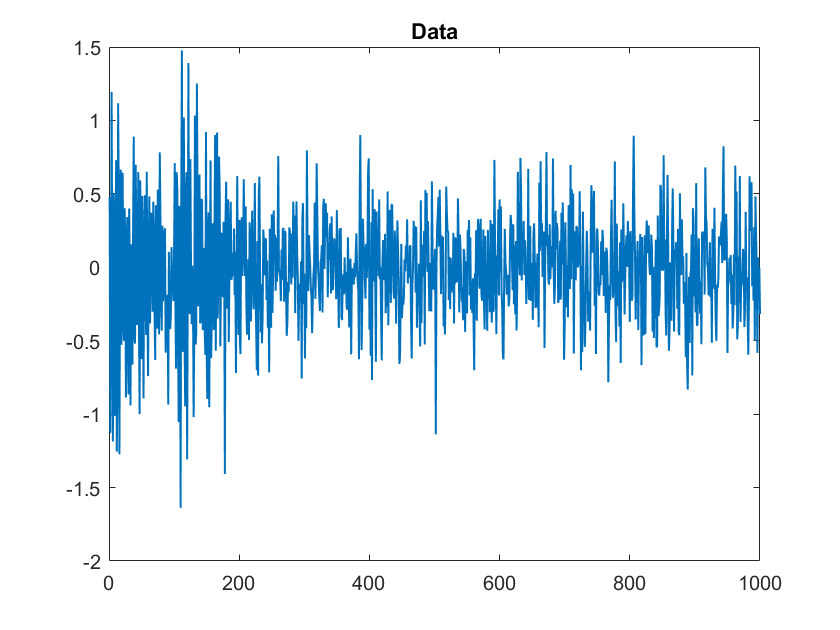

clear all;
% Build example dynamics matrix
seed = 17;
n = 2;                  % Matrix size; should be even
m = 1000;               % Number of data points
eigenvalue_min = 0.95;  % Minimum eigenvalue; 1.0 = stable
[X_dmd, A] = test_dmd_dat(n, m, 0, eigenvalue_min, seed);

% Build random controller
ctr_timing = 100:105;
U = zeros(1,m-1);
U(ctr_timing) = 1.0;

% Generate controlled data
x0 = X_dmd(:,1);
B = ones(n,1);
X_true = real(calc_reconstruction_dmd(x0, [], A, B, U));
% Add noise
noise = 0.3;
X = X_true + noise*randn(size(X_true));

% Plot
figure('DefaultAxesFontSize', 24);
plot(1:m,X(1,:), 'LineWidth', 1)
title("Data")

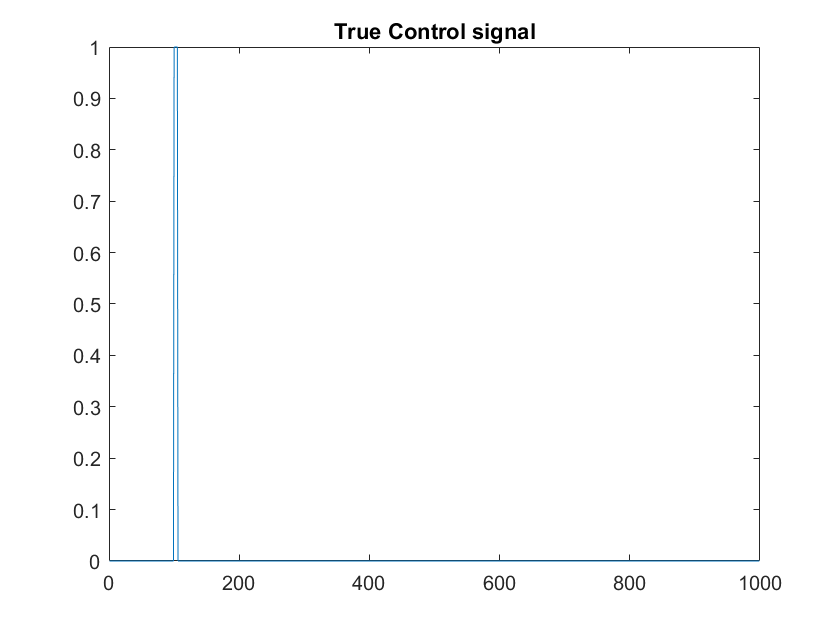


figure;
plot(1:m-1,U)
title("True Control signal")

## Get path of control signals

% Returns a data class with control signals of increasing sparsity
settings = struct('r_ctr',1, ... % Number of control signals to search for
                  'verbose',false, ... 
                   'num_iter',100); % Number of iterations
control_signal_path = learn_control_signals(X, settings);

## Cross-validation

% Calculate best control signal
objective_function = 'acf';
control_signal_path.calc_best_control_signal(objective_function)

best_U = control_signal_path.U;

% Plot
objective_vals = control_signal_path.objective_values;

figure('DefaultAxesFontSize', 24);
plot(objective_vals)
title('Objective function')
xlabel('Iteration')

figure('DefaultAxesFontSize', 24);
subplot(2,1,1)
plot(U, 'linewidth', 2)
title("True Control Signal")
subplot(2,1,2)
plot(best_U, 'linewidth', 2)
title("Learned Control signal")

figure('DefaultAxesFontSize', 24);
ind = 95:110;
subplot(2,1,1)
plot(ind, U(ind), 'linewidth', 2)
title("True Control Signal (Zoomed)")
subplot(2,1,2)
plot(ind, best_U(ind), 'linewidth', 2)
title("Learned Control signal (Zoomed)")

